# 10.2 Trigonometric Interpolation

## CP3


$$F_p^{-1} \sqrt{\frac{p}{n}} F_n x$$


de blå sirklene er datapunktene, den blå kurven er $f(t) = e^t
$ og den oransje kurven er interpolasjonen.

range = (0:1/8:7/8)'

range =          0
    0.1250
    0.2500
    0.3750
    0.5000
    0.6250
    0.7500
    0.8750


long_range = linspace(0,1,100)

long_range =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


x = arrayfun(@exp, range);
hold off;
dftinterp([0, 1], x, 8, 100)

ans =     1.0000
    0.9334
    0.8844
    0.8532
    0.8390
    0.8407
    0.8565
    0.8842
    0.9213
    0.9651


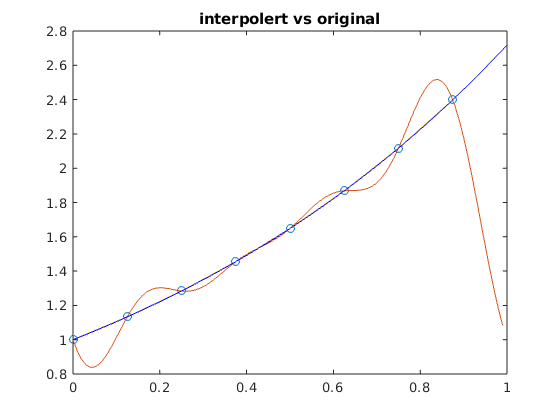

hold on;
plot(range, x)
plot(long_range, arrayfun(@exp, long_range), 'color', 'blue')
title('interpolert vs original')

function xp=dftinterp(intervall,x,n,p)
c = intervall(1);
d = intervall(2);
t=c+(d-c)*(0:n-1)/n;
tp=c+(d-c)*(0:p-1)/p;
y=fft(x); % apply DFT
yp=zeros(p,1); % yp will hold coefficients for ifft
yp(1:n/2+1)=y(1:n/2+1); % move n frequencies from n to p
yp(p-n/2+2:p)=y(n/2+2:n); % same for upper tier
xp=real(ifft(yp))*(p/n); % invert fft to recover data
plot(t,x,'o',tp,xp) % plot data points and interpolant
end